# Estudio del Perceptrón

En este script estudiamos la capacidad del perceptrón en clasificación de datos en dos clases.

Modificación del script original de Valeri Makarov para incluir el cálculo de $\alpha$ y número de pasos de entrenamiento óptimos.

18 de octubre de 2020

## Generamos datos (2D) separados en 2 clases

Generamos un conjunto $X$ de $N$ puntos en un plano. Los puntos que están por encima de la recta $y=ax+b$ pertenecen a la Clase A y los puntos por debajo a la Clase B. La variable $Y$ define la clase. Si $y_i=0$, entonces el punto $i$ pertence a la clase A. 

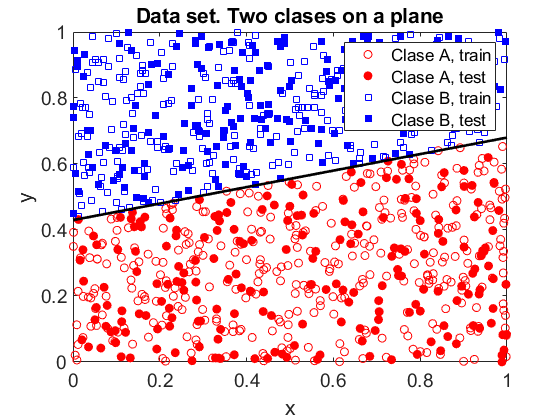

clear
N = 1000;  % cantidad total de puntos
M = 600;   % número de puntos en el conjunto de entranmiento
n = 2;     % dimensión (plano)
a = .25;   % parametros que definen las clases
b = .43;

X = rand(n, N);        % conjunto de puntos
line = @(x) a * x + b; % recta de separación
Y = zeros(N, 1);       % Variable de clase
Y(X(2,:) > line(X(1,:))) = 1; % clase B

idTrain = true(N,1);       % Conjunto entrenamiento
idTrain(M+1:end) = false;  % Conjunto test
ClaseA = (Y == 0);         % Clase A

% Dibujamos 
figure
plot(X(1, ClaseA & idTrain),X(2,ClaseA & idTrain),'ro')
hold on
plot(X(1, ClaseA & ~idTrain), X(2, ClaseA & ~idTrain),'ro','MarkerFaceColor','r')
plot(X(1, ~ClaseA & idTrain), X(2, ~ClaseA & idTrain),'bs')
plot(X(1, ~ClaseA & ~idTrain), X(2, ~ClaseA & ~idTrain),'bs','MarkerFaceColor','b')
plot([0,1],line([0,1]),'k','LineWidth',2)
set(gca,'FontSize',14)
legend({'Clase A, train','Clase A, test','Clase B, train','Clase B, test'})
title('Data set. Two clases on a plane')
xlabel('x'); ylabel('y')

## Modelo del perceptrón

El perceptrón genera la salida según la ecuación $z=F(\langle \vec{w}, \vec{x}  \rangle - \theta)$, donde $\vec{w}$ es el vector de pesos, $\theta$ es el umbral y $F(\cdot)$ es la función de transferencia (Heavyside). Fijamos los pesos de manera aleatoria y  comprobamos el error relativo en el conjunto de test. El error relativo es el número de puntos clasificados incorrectamente entre la cantidad total de los puntos (el valor 0.5 corresponde a la clasificación al azar).  

F = @(u) 1.0 * (u > 0); % Función de activación
Theta = 0.5;            % Umbral (usamos fijo)

Perceptron = @(w,x) F(w*x - Theta)'; % Modelo del perceptrón
ErrorRelativo = @(z,y) 1 - sum(z(:) == y(:))/length(z); % Error relativo

W = rand(1, n);        % Pesos (arbitrarios al principio)
Z = Perceptron(W, X);  % Salida del perceptrón (el conjunto entero)

E0 = ErrorRelativo(Z(~idTrain), Y(~idTrain)); % el error

disp('=============== Antes de entrenamiento =================')

=============== Antes de entrenamiento =================


disp(['El error relativo (conjunto de test) = ' num2str(100*E0,3) '%'])

El error relativo (conjunto de test) = 36.5%


## Entrenamiento del percetrón

Para el entrenamiento usamos la regla delta. Según esta regla iterativa en cada paso los pesos sinápticos se actualizan  $\vec{w}_{n+1}:=\vec{w}_n+\alpha \delta_n \vec{x}_n$, donde $\alpha >0$ es una constante que se llama el ratio de aprendizaje. En general hay que elegirla suficientemente pequeña. $\delta_n$ es la función del error. Se puede demostrar (ejercicio) que podemos elegirla como $\delta(y,z) = y-z$, donde $y\in \{0,1\}$ es la variable de clase y $z$ es la salida del perceptrón, $z\in \{0,1\}$, producida por el vector $x_n$.

Vamos a determinar $\alpha$ y el número de pasos de entrenamiento empíricamente, de forma que se minimice el error relativo en el conjunto de test.

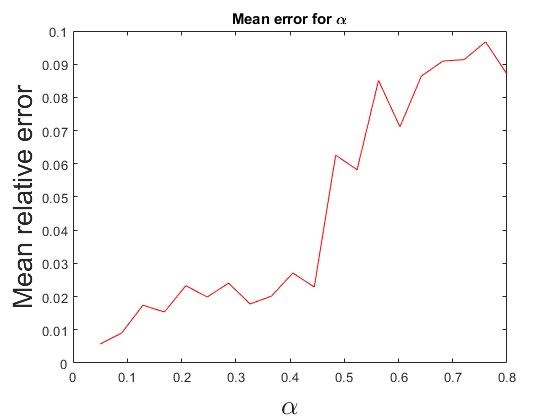

NAlphas = 20;
Alphas = linspace(.05, .8, NAlphas);
Ntrains = 100;
Errors = zeros(NAlphas, 1);
for a = 1:NAlphas
    alpha = Alphas(a);
    E = 0;
    for i = 1:Ntrains
        W = train(X(:, idTrain), Y(idTrain, :), 5000, alpha, Theta, false);
        % Resultado en conjunto de test
        Z = Perceptron(W, X(:, ~idTrain));
        E = E + ErrorRelativo(Z, Y(~idTrain));
    end
    Errors(a) = E / Ntrains;
end

figure
plot(Alphas, Errors, 'color', 'red')
title('Mean error for \alpha')
xlabel('\alpha','FontSize',20)
ylabel('Mean relative error','FontSize',20)


[~, i] = min(Errors);
alpha = Alphas(i);
disp(['Mejor alpha = ' num2str(alpha)])

Mejor alpha = 0.05


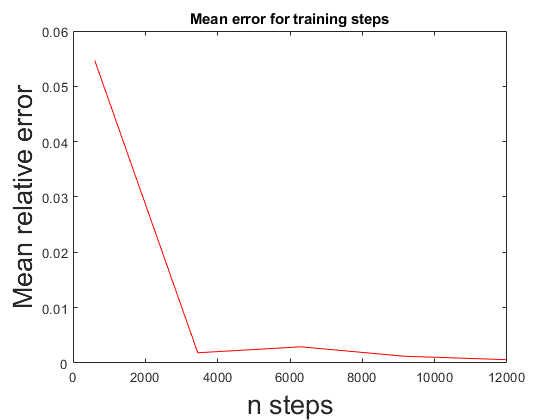


NNSteps = 5;
NSteps = linspace(M, M * 20, NNSteps);
Errors = zeros(NNSteps, 1);
for s = 1:NNSteps
    steps = NSteps(s);
    E = 0;
    for i = 1:Ntrains
        W = train(X(:, idTrain), Y(idTrain, :), steps, alpha, Theta, false);
        % Resultado en conjunto de test
        Z = Perceptron(W, X(:, ~idTrain));
        E = E + ErrorRelativo(Z, Y(~idTrain));
    end
    Errors(s) = E / Ntrains;
end

figure
plot(NSteps, Errors, 'color', 'red')
title('Mean error for training steps')
xlabel('n steps','FontSize',20)
ylabel('Mean relative error','FontSize',20)


[~, i] = min(Errors);
steps = NSteps(i);
disp(['Mejor número de pasos de entrenamiento = ' num2str(steps)])

Mejor número de pasos de entrenamiento = 12000


## Entrenamiento final y prueba del perceptrón

Finalmente, entrenamos el perceptrón con los hiperparámetros obtenidos y lo probamos con todos los datos para ver qué recta ha obtenido y cuántos fallos produce.

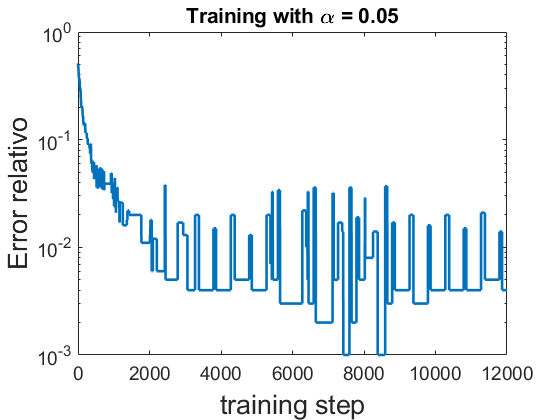

W = train(X, Y, steps, alpha, Theta, true);

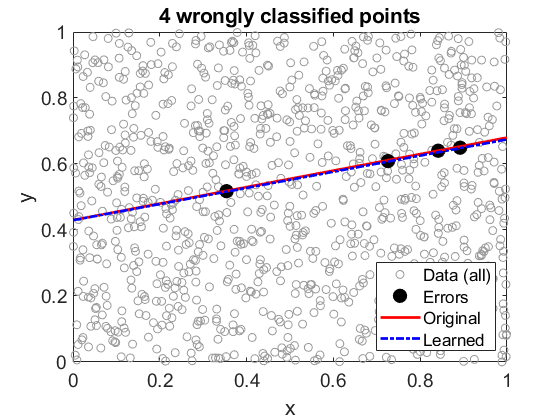

Z = Perceptron(W, X);

figure
plot(X(1, :), X(2, :),'o','Color',0.6*[1 1 1])
E = (Z ~= Y); 
hold on
plot(X(1, E), X(2, E),'ko','MarkerFaceColor','k','MarkerSize',10)
plot([0,1],line([0,1]),'r','LineWidth',2)
plot([0,1],(Theta - W(1)*[0,1])/W(2),'b-.','LineWidth',2)
set(gca,'FontSize',14)
if size(E(E == 1), 1) == 0
    legend({'Data (all)','Original','Learned'},...
        'Location','southeast')
else
    legend({'Data (all)','Errors','Original','Learned'},...
        'Location','southeast')
end
title([num2str(sum(E))...
   ' wrongly classified points'])
xlabel('x'); ylabel('y')

function W = train(X, Y, Ntrn, alpha, Theta, plotError)
    n = size(X, 1);
    M = size(X, 2);
    W = rand(1, n);   % Pesos arbitrarios al principio
    
    F = @(u) 1.0 * (u > 0); % Función de activación
    Perceptron = @(w,x) F(w*x - Theta)'; % Modelo del perceptrón
    ErrorRelativo = @(z,y) 1 - sum(z(:) == y(:))/length(z); % Error relativo
    
    Etrn = zeros(Ntrn,1);
    for k = 1:Ntrn    
        % Entrenamiento
        kk = mod(k-1, M)+1;          % indice sobre el conjunto de entrenamiento (1:M) 
        z = Perceptron(W, X(:,kk));  % salida del perceptron
        delta = Y(kk) - z;           % error
        W = W + alpha*delta*X(:,kk)';% actualización de pesos
        
        % Errores
        Z = Perceptron(W, X);
        Etrn(k) = ErrorRelativo(Z, Y);
    end
    
    if plotError
        % Dibujamos 
        figure
        semilogy(1:Ntrn, Etrn + 1e-6,'LineWidth', 2)
        set(gca,'FontSize',14)
        xlabel('training step','FontSize',20)
        ylabel('Error relativo','FontSize',20)
        title(['Training with \alpha = ' num2str(alpha)])
    end
end